Q3

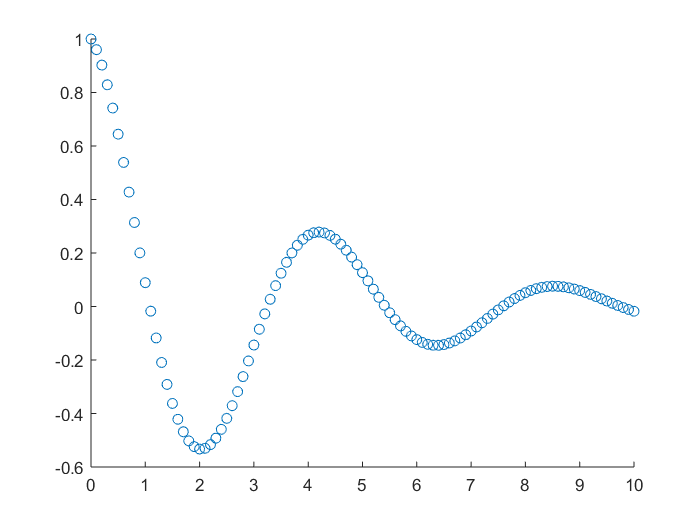

data = importdata('Ass_2_Q3_data.txt');
scatter(data(:,1), data(:,2))

length(data)

ans =    101


roots = [];

x = data(:,1);
f = data(:,2);
for i=2:length(data)
    % we know there is a root if there is a sign change in between points
    if f(i)*f(i-1) < 0
        x_i1 = x(i) - (f(i)*(x(i)-x(i-1))/(f(i)-f(i-1)));
        roots = [roots, x(i)];
    end
end
roots

roots =    1.100000000000000   3.300000000000000   5.500000000000000   7.600000000000000   9.800000000000001


T = 0

T =      0


% calculate the avg period by using all roots
for i=2:length(roots)
    T = T + roots(i)-roots(i-1);
end
T = T/4

T =    2.175000000000000


% find the frequency
f = 1/T

f =    0.459770114942529
